%%
% 5281873
clc
close all
clear all

% setup
a = 5; b = 8; c = 3;

NCS.A = [a-b 0.5-c;
         0   1];

NCS.B = [0; 1];

NCS.nx = 2;

NCS.K = [-2 1.6];
% NCS.K = [-2 0];

NCS.h = 0.2;

%% 4.1

syms h tau s

NCS_small_delay.Fx = expm(NCS.A*h);

temp = expm(NCS.A*s);
NCS_small_delay.Fu = int(temp, s, h-tau, h)*NCS.B;

NCS_small_delay.G1 = int(temp, s, 0, h-tau)*NCS.B;

NCS_small_delay.F = [NCS_small_delay.Fx, NCS_small_delay.Fu;
                     0 0 0];
NCS_small_delay.G = [NCS_small_delay.G1;
                    1];

[V, J] = jordan(sym(10*NCS.A));

NCS_small_delay.Q = inv(V);
NCS_small_delay.J = J/10;

clear V J temp

NCS_small_delay.F

 
ans =
 
        [1. exp(-3. h) ,

        0.625000000000000 exp(-3. h) - 0.625000000000000 exp(h) ,

        0.6250000000 exp(h - 1. tau) + 0.2083333333 exp(-3. h + 3. tau)

         - 0.6250000000 exp(h) - 0.2083333333 exp(-3. h)]

        [0. , exp(h) , -exp(h - tau) + exp(h)]

        [0 , 0 , 0]


% 
% NCS_small_delay.G

%% 4.2
NCS_polytopic.alpha_1 = expm(-3*(h-tau)); 
NCS_polytopic.alpha_2 = expm((h-tau)); 


NCS_polytopic.F1 = [0 0 5/24; 0 0 0; 0 0 0];
NCS_polytopic.F2 = [0 0 5/8; 0 0 -1; 0 0 0];
NCS_polytopic.F0 = NCS_small_delay.F - NCS_polytopic.F1*NCS_polytopic.alpha_1 - NCS_polytopic.F2*NCS_polytopic.alpha_2;

NCS_polytopic.G0 = [5/6; -1; 1];
NCS_polytopic.G1 = [-5/24;0; 0];
NCS_polytopic.G2 = [-5/8; 1; 0];


K = [NCS.K 0];


h_samples = 0:0.01:0.5;

result = zeros(1, length(h_samples));

for i=1:1:length(h_samples)


    h_sample = h_samples(i);

    tau_lb = 0; tau_ub = h_sample;

    alpha_1_lb = double(subs(NCS_polytopic.alpha_1, [h, tau], [h_sample, tau_lb]));
    alpha_1_ub = double(subs(NCS_polytopic.alpha_1, [h, tau], [h_sample, tau_ub]));
    alpha_2_lb = double(subs(NCS_polytopic.alpha_2, [h, tau], [h_sample, tau_lb]));
    alpha_2_ub = double(subs(NCS_polytopic.alpha_2, [h, tau], [h_sample, tau_ub]));
 

    F0 = subs(NCS_polytopic.F0, [h, tau], [h_sample, tau_ub])
    G0 = subs(NCS_polytopic.G0, [h, tau], [h_sample, tau_ub])
    F1_vertices = double(F0 + alpha_1_lb * NCS_polytopic.F1 + alpha_2_lb * NCS_polytopic.F2);
    G1_vertices = double(G0 + alpha_1_lb * NCS_polytopic.G1 + alpha_2_lb * NCS_polytopic.G2);
    F2_vertices = double(F0 + alpha_1_lb * NCS_polytopic.F1 + alpha_2_ub * NCS_polytopic.F2);
    G2_vertices = double(G0 + alpha_1_lb * NCS_polytopic.G1 + alpha_2_ub * NCS_polytopic.G2);
    F3_vertices = double(F0 + alpha_1_ub * NCS_polytopic.F1 + alpha_2_lb * NCS_polytopic.F2);
    G3_vertices = double(G0 + alpha_1_ub * NCS_polytopic.G1 + alpha_2_lb * NCS_polytopic.G2);
    F4_vertices = double(F0 + alpha_1_ub * NCS_polytopic.F1 + alpha_2_ub * NCS_polytopic.F2);
    G4_vertices = double(G0 + alpha_1_ub * NCS_polytopic.G1 + alpha_2_ub * NCS_polytopic.G2);


    cvx_clear
    cvx_begin sdp

        variable P(3,3) semidefinite

        subject to
            (F1_vertices - G1_vertices*K)'*P*(F1_vertices - G1_vertices*K) - P <= -0.001*P;
            (F2_vertices - G2_vertices*K)'*P*(F2_vertices - G2_vertices*K) - P <= -0.001*P;
            (F3_vertices - G3_vertices*K)'*P*(F3_vertices - G3_vertices*K) - P <= -0.001*P;
            (F4_vertices - G4_vertices*K)'*P*(F4_vertices - G4_vertices*K) - P <= -0.001*P;
            P >= 0.001*eye(3);
    cvx_end

    if (cvx_status=="Solved")    
        result(i)=1;
    end


end

 
F0 =
 
        [1. exp(-0.) , 0.625000000000000 exp(-0.) - 0.625000000000000 exp(0) ,

        0.4166666667 exp(-0.) + 0.2083333333 exp(0.) - 1.45833333333333 exp(0)

        ]

        [0. , exp(0) , exp(0)]

        [0. , 0. , 0.]


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+02|4.2e+01|1.8e+03| 9.920000e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.901|0.981|2.9e+01|9.1e-01|1.0e+02|-6.653283e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.965|0.942|9.9e-01|6.3e-02|4.2e+00|-6.967988e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.830|0.822|1.7e-01|1.2e-02|9.1e-01|-2.926999e-04  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.0300000000000000) ,

        0.625000000000000 exp(-0.0300000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                                ]
         - 0.2083333333 exp(-0.0300000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0100000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+02|4.2e+01|1.8e+03|-7.731103e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.865|0.979|3.9e+01|1.0e+00|1.4e+02|-7.772305e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.909|1.000|3.6e+00|1.0e-02|1.3e+01|-1.152122e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.981|1.000|6.8e-02|1.0e-03|2.4e-01|-2.192233e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.0600000000000000) ,

        0.625000000000000 exp(-0.0600000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                                ]
         - 0.2083333333 exp(-0.0600000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0200000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+02|4.2e+01|1.8e+03|-5.597420e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.818|0.975|5.2e+01|1.2e+00|1.9e+02|-7.036336e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.909|1.000|4.7e+00|1.0e-02|1.7e+01|-1.187082e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.984|1.000|7.4e-02|1.0e-03|2.7e-01|-1.883704e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.0900000000000000) ,

        0.625000000000000 exp(-0.0900000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                                ]
         - 0.2083333333 exp(-0.0900000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0300000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+02|4.2e+01|1.8e+03|-3.628956e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.788|0.971|6.1e+01|1.3e+00|2.3e+02|-6.428282e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.903|1.000|5.8e+00|1.0e-02|2.2e+01|-1.218973e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|8.5e-02|1.0e-03|3.2e-01|-1.798374e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.120000000000000) ,

        0.625000000000000 exp(-0.120000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.120000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0400000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03|-1.816332e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.773|0.968|6.5e+01|1.5e+00|2.6e+02|-5.965683e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.890|1.000|7.1e+00|1.0e-02|2.8e+01|-1.305928e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.0e-01|1.0e-03|3.9e-01|-1.849809e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.150000000000000) ,

        0.625000000000000 exp(-0.150000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.150000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0500000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03|-1.507553e-04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.768|0.965|6.6e+01|1.6e+00|2.8e+02|-5.644348e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.873|1.000|8.4e+00|1.0e-02|3.5e+01|-1.375301e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.1e-01|1.0e-03|4.8e-01|-1.902202e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.180000000000000) ,

        0.625000000000000 exp(-0.180000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.180000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0600000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 1.376016e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.770|0.963|6.5e+01|1.7e+00|2.9e+02|-5.449850e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.855|1.000|9.4e+00|1.0e-02|4.1e+01|-1.407888e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.3e-01|1.0e-03|5.6e-01|-1.921024e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.210000000000000) ,

        0.625000000000000 exp(-0.210000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.210000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0700000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 2.771706e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.776|0.961|6.3e+01|1.7e+00|2.9e+02|-5.362946e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.836|1.000|1.0e+01|1.0e-02|4.7e+01|-1.410102e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.4e-01|1.0e-03|6.3e-01|-1.910646e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.240000000000000) ,

        0.625000000000000 exp(-0.240000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.240000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0800000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 4.043548e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.785|0.959|6.0e+01|1.8e+00|2.9e+02|-5.363033e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.819|1.000|1.1e+01|1.0e-02|5.2e+01|-1.390711e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|6.9e-01|-1.879521e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.270000000000000) ,

        0.625000000000000 exp(-0.270000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.270000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.0900000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 5.198317e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.795|0.958|5.7e+01|1.9e+00|2.8e+02|-5.430346e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.802|1.000|1.1e+01|1.0e-02|5.5e+01|-1.357790e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|7.4e-01|-1.835728e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.300000000000000) ,

        0.625000000000000 exp(-0.300000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.300000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.100000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 6.242350e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.806|0.956|5.4e+01|1.9e+00|2.7e+02|-5.547575e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.787|1.000|1.1e+01|1.0e-02|5.8e+01|-1.322070e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|7.8e-01|-1.791107e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.330000000000000) ,

        0.625000000000000 exp(-0.330000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.330000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.110000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 7.181578e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.816|0.955|5.1e+01|2.0e+00|2.6e+02|-5.700507e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.775|1.000|1.1e+01|1.0e-02|6.0e+01|-1.291502e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|8.0e-01|-1.754671e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.360000000000000) ,

        0.625000000000000 exp(-0.360000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.360000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.120000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 8.021542e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.825|0.953|4.8e+01|2.1e+00|2.6e+02|-5.878028e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.764|1.000|1.1e+01|1.0e-02|6.1e+01|-1.268856e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|8.2e-01|-1.729566e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.390000000000000) ,

        0.625000000000000 exp(-0.390000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.390000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.130000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 8.767423e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.834|0.951|4.5e+01|2.2e+00|2.5e+02|-6.071774e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.755|1.000|1.1e+01|1.0e-02|6.1e+01|-1.260960e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|8.2e-01|-1.724548e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.420000000000000) ,

        0.625000000000000 exp(-0.420000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.420000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.140000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 9.424054e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.841|0.949|4.3e+01|2.3e+00|2.4e+02|-6.275690e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.748|1.000|1.1e+01|1.0e-02|6.0e+01|-1.274451e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.5e-01|1.0e-03|8.2e-01|-1.748407e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.450000000000000) ,

        0.625000000000000 exp(-0.450000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.450000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.150000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 9.995947e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.847|0.947|4.1e+01|2.3e+00|2.3e+02|-6.485716e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.743|1.000|1.1e+01|1.0e-02|5.9e+01|-1.317164e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.4e-01|1.0e-03|8.1e-01|-1.811892e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.480000000000000) ,

        0.625000000000000 exp(-0.480000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.480000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.160000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 1.048731e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.852|0.944|4.0e+01|2.4e+00|2.3e+02|-6.699611e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.741|1.000|1.0e+01|1.0e-02|5.8e+01|-1.396443e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.4e-01|1.0e-03|7.9e-01|-1.924880e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.510000000000000) ,

        0.625000000000000 exp(-0.510000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.510000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.170000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 1.090205e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.856|0.941|3.9e+01|2.6e+00|2.2e+02|-6.916741e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.743|1.000|9.9e+00|1.0e-02|5.5e+01|-1.541904e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.4e-01|1.0e-03|7.5e-01|-2.124640e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.540000000000000) ,

        0.625000000000000 exp(-0.540000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.540000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.180000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 1.124383e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.860|0.938|3.8e+01|2.7e+00|2.2e+02|-7.137662e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.751|0.999|9.3e+00|1.4e-02|5.1e+01|-1.741821e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|1.3e-01|1.0e-03|7.2e-01|-2.470347e-05  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.570000000000000) ,

        0.625000000000000 exp(-0.570000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.570000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.190000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 1.151602e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.862|0.934|3.7e+01|2.9e+00|2.2e+02|-7.363614e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.766|0.924|8.6e+00|2.3e-01|4.9e+01|-1.998633e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.908|1.000|7.9e-01|1.0e-03|4.6e+00|-1.428746e-04  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.600000000000000) ,

        0.625000000000000 exp(-0.600000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.600000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.200000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.172178e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.864|0.930|3.6e+01|3.1e+00|2.2e+02|-7.596100e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.777|0.864|8.1e+00|4.3e-01|4.9e+01|-2.484564e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.807|0.811|1.6e+00|8.1e-02|1.1e+01|-4.926354e-04  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.630000000000000) ,

        0.625000000000000 exp(-0.630000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.630000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.210000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.186401e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.865|0.925|3.6e+01|3.3e+00|2.2e+02|-7.836658e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.792|0.816|7.4e+00|6.1e-01|5.0e+01|-3.163320e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.811|0.505|1.4e+00|3.0e-01|1.8e+01|-1.168415e-03  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.660000000000000) ,

        0.625000000000000 exp(-0.660000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.660000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.220000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.194543e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.865|0.921|3.5e+01|3.4e+00|2.2e+02|-8.086768e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.821|0.779|6.3e+00|7.7e-01|4.9e+01|-3.963748e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.758|0.484|1.5e+00|4.0e-01|2.7e+01|-3.075284e-03  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.690000000000000) ,

        0.625000000000000 exp(-0.690000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.690000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.230000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.196852e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.916|3.5e+01|3.6e+00|2.3e+02|-8.347822e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.864|0.754|4.8e+00|9.0e-01|4.6e+01|-4.901618e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.866|0.611|6.4e-01|3.5e-01|2.2e+01|-4.763411e-03  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.720000000000000) ,

        0.625000000000000 exp(-0.720000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.720000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.240000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.193559e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.911|3.5e+01|3.8e+00|2.3e+02|-8.621124e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.868|0.741|4.6e+00|1.0e+00|5.0e+01|-6.168241e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.690|1.0e-04|3.1e-01|1.9e+01|-6.678278e-03  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.750000000000000) ,

        0.625000000000000 exp(-0.750000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.750000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.250000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.184875e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.907|3.5e+01|4.0e+00|2.3e+02|-8.907877e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.855|0.738|5.0e+00|1.1e+00|5.5e+01|-7.459961e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.966|0.663|1.7e-01|3.6e-01|2.3e+01|-8.797054e-03  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.780000000000000) ,

        0.625000000000000 exp(-0.780000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.780000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.260000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.170997e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.902|3.5e+01|4.2e+00|2.3e+02|-9.209168e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.847|0.722|5.3e+00|1.2e+00|6.0e+01|-8.650113e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.687|1.2e-04|3.7e-01|2.2e+01|-1.007448e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.810000000000000) ,

        0.625000000000000 exp(-0.810000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.810000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.270000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.152101e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.898|3.4e+01|4.4e+00|2.3e+02|-9.525947e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.839|0.704|5.6e+00|1.3e+00|6.6e+01|-9.894364e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.700|1.0e-04|4.0e-01|2.3e+01|-1.149770e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.840000000000000) ,

        0.625000000000000 exp(-0.840000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.840000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.280000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.128350e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.866|0.893|3.4e+01|4.6e+00|2.4e+02|-9.858996e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.831|0.688|5.8e+00|1.4e+00|7.3e+01|-1.114061e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.713|9.0e-05|4.1e-01|2.3e+01|-1.287009e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.870000000000000) ,

        0.625000000000000 exp(-0.870000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.870000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.290000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.099894e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.867|0.889|3.4e+01|4.8e+00|2.4e+02|-1.020890e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.826|0.678|5.9e+00|1.5e+00|7.8e+01|-1.231200e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.722|8.0e-05|4.3e-01|2.4e+01|-1.421132e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.900000000000000) ,

        0.625000000000000 exp(-0.900000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.900000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.300000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 1.066866e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.867|0.886|3.4e+01|4.9e+00|2.4e+02|-1.057599e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.824|0.673|6.0e+00|1.6e+00|8.1e+01|-1.340572e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.730|7.2e-05|4.4e-01|2.4e+01|-1.546740e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.930000000000000) ,

        0.625000000000000 exp(-0.930000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.930000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.310000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 1.029388e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.868|0.882|3.3e+01|5.1e+00|2.4e+02|-1.096036e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.824|0.672|5.9e+00|1.7e+00|8.4e+01|-1.442373e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.739|6.5e-05|4.4e-01|2.3e+01|-1.660674e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.960000000000000) ,

        0.625000000000000 exp(-0.960000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.960000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.320000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 9.875681e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.869|0.879|3.3e+01|5.2e+00|2.4e+02|-1.136178e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.826|0.673|5.8e+00|1.7e+00|8.5e+01|-1.536616e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.751|6.0e-05|4.3e-01|2.2e+01|-1.762495e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-0.990000000000000) ,

        0.625000000000000 exp(-0.990000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                               ]
         - 0.2083333333 exp(-0.990000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.330000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 9.415035e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.871|0.876|3.3e+01|5.3e+00|2.4e+02|-1.177970e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.826|0.678|5.7e+00|1.7e+00|8.5e+01|-1.623868e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.761|5.7e-05|4.1e-01|2.1e+01|-1.867232e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.02000000000000) ,

        0.625000000000000 exp(-1.02000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.02000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.340000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 8.912798e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.872|0.874|3.2e+01|5.4e+00|2.4e+02|-1.221322e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.827|0.683|5.5e+00|1.7e+00|8.5e+01|-1.708497e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.758|5.4e-05|4.2e-01|2.2e+01|-2.029573e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.05000000000000) ,

        0.625000000000000 exp(-1.05000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.05000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.350000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 8.369720e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.875|0.872|3.1e+01|5.5e+00|2.4e+02|-1.266112e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.829|0.689|5.4e+00|1.7e+00|8.4e+01|-1.788174e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.757|5.3e-05|4.2e-01|2.3e+01|-2.204550e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.08000000000000) ,

        0.625000000000000 exp(-1.08000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.08000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.360000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 7.786450e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.877|0.869|3.1e+01|5.6e+00|2.4e+02|-1.313035e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.833|0.696|5.1e+00|1.7e+00|8.3e+01|-1.866844e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.761|5.4e-05|4.1e-01|2.3e+01|-2.382894e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.11000000000000) ,

        0.625000000000000 exp(-1.11000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.11000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.370000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 7.163539e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.878|0.867|3.0e+01|5.7e+00|2.4e+02|-1.362333e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.839|0.701|4.9e+00|1.7e+00|8.2e+01|-1.946403e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.771|5.4e-05|3.9e-01|2.3e+01|-2.540825e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.14000000000000) ,

        0.625000000000000 exp(-1.14000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.14000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.380000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 6.501446e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.881|0.866|3.0e+01|5.8e+00|2.4e+02|-1.412389e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.847|0.698|4.6e+00|1.7e+00|8.2e+01|-2.020623e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.787|4.7e-05|3.7e-01|2.1e+01|-2.617274e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.17000000000000) ,

        0.625000000000000 exp(-1.17000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.17000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.390000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 5.800545e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|0.865|2.9e+01|5.8e+00|2.3e+02|-1.462867e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.856|0.696|4.2e+00|1.8e+00|8.2e+01|-2.089869e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.805|4.3e-05|3.5e-01|1.9e+01|-2.671241e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.20000000000000) ,

        0.625000000000000 exp(-1.20000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.20000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.400000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 5.061123e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.887|0.864|2.8e+01|5.8e+00|2.3e+02|-1.513436e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.866|0.695|3.8e+00|1.8e+00|8.1e+01|-2.154411e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.827|4.1e-05|3.1e-01|1.7e+01|-2.700284e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.23000000000000) ,

        0.625000000000000 exp(-1.23000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.23000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.410000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 4.283388e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.891|0.864|2.7e+01|5.8e+00|2.3e+02|-1.563775e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.879|0.695|3.3e+00|1.8e+00|7.9e+01|-2.214423e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.851|4.0e-05|2.7e-01|1.4e+01|-2.702125e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.26000000000000) ,

        0.625000000000000 exp(-1.26000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.26000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.420000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 3.467473e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.895|0.865|2.6e+01|5.8e+00|2.2e+02|-1.613581e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.894|0.696|2.8e+00|1.8e+00|7.7e+01|-2.269988e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.880|4.0e-05|2.1e-01|1.1e+01|-2.675765e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.29000000000000) ,

        0.625000000000000 exp(-1.29000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.29000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.430000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 2.613436e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.900|0.866|2.5e+01|5.8e+00|2.2e+02|-1.662571e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.909|0.695|2.3e+00|1.8e+00|7.5e+01|-2.327286e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.907|4.0e-05|1.6e-01|7.8e+00|-2.639556e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.32000000000000) ,

        0.625000000000000 exp(-1.32000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.32000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.440000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 1.721267e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.904|0.867|2.4e+01|5.7e+00|2.2e+02|-1.710486e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.924|0.694|1.8e+00|1.8e+00|7.4e+01|-2.386647e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.932|4.1e-05|1.2e-01|5.4e+00|-2.602239e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.35000000000000) ,

        0.625000000000000 exp(-1.35000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.35000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.450000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 7.908865e-04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.909|0.868|2.3e+01|5.7e+00|2.1e+02|-1.757089e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.945|0.697|1.2e+00|1.7e+00|7.1e+01|-2.432652e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.957|4.1e-05|7.5e-02|3.1e+00|-2.547450e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.38000000000000) ,

        0.625000000000000 exp(-1.38000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.38000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.460000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03|-1.778478e-04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.870|2.1e+01|5.6e+00|2.0e+02|-1.802174e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.971|0.701|6.2e-01|1.7e+00|6.7e+01|-2.465745e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.975|4.1e-05|4.3e-02|1.7e+00|-2.504669e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.41000000000000) ,

        0.625000000000000 exp(-1.41000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.41000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.470000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03|-1.185141e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.920|0.871|2.0e+01|5.5e+00|2.0e+02|-1.845556e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.706|2.8e-05|1.6e+00|6.3e+01|-2.492369e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.983|4.1e-05|2.8e-02|1.1e+00|-2.503396e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.44000000000000) ,

        0.625000000000000 exp(-1.44000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.44000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.480000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03|-2.231257e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.925|0.873|1.9e+01|5.5e+00|1.9e+02|-1.887079e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.712|2.7e-05|1.6e+00|5.9e+01|-2.492615e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.983|4.1e-05|2.7e-02|1.0e+00|-2.504460e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.47000000000000) ,

        0.625000000000000 exp(-1.47000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.47000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.490000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03|-3.316519e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.931|0.875|1.7e+01|5.4e+00|1.9e+02|-1.926612e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.718|2.7e-05|1.5e+00|5.6e+01|-2.486164e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.983|4.0e-05|2.7e-02|9.6e-01|-2.498923e-02  0.000000e+

 
F0 =
 
        [
        [1. exp(-1.50000000000000) ,

        0.625000000000000 exp(-1.50000000000000) - 0.625000000000000 %1 ,

                             -10
        -0.333333360913457 10    exp(0.) - 0.6250000000 %1

                                              ]
         - 0.2083333333 exp(-1.50000000000000)]

        [0. , %1 , %1]

        [0. , 0. , 0.]

  %1 := exp(0.500000000000000)


 
G0 =
 
                              [0.833333333333333]
                              [                 ]
                              [       -1.       ]
                              [                 ]
                              [       1.        ]


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03|-4.441305e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.936|0.877|1.6e+01|5.3e+00|1.8e+02|-1.964046e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.724|2.7e-05|1.5e+00|5.3e+01|-2.473075e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.983|4.0e-05|2.6e-02|9.2e-01|-2.486863e-02  0.000000e+

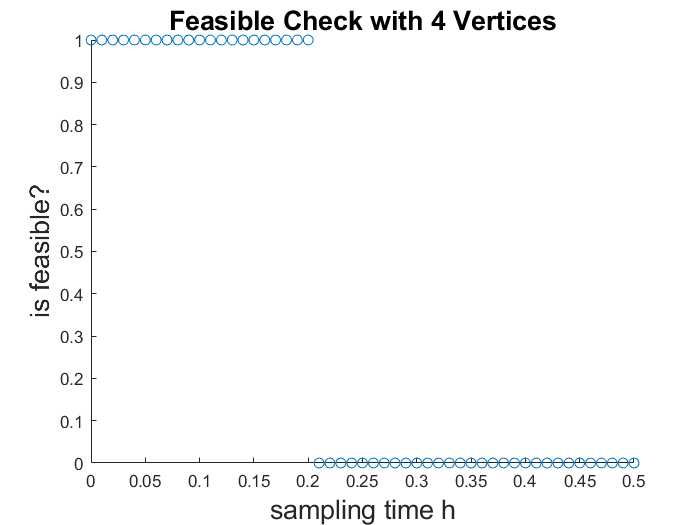



figure

% contour(result)
result(1)=1;


scatter(h_samples,result)

xlabel("sampling time h", 'FontSize', 16); 
ylabel("is feasible?", 'FontSize', 16);

title("Feasible Check with 4 Vertices", 'FontSize', 16)

%% 4.3
h_samples = 0:0.025:1;
tau_samples = h_samples;
plot_h = zeros([1, (length(h_samples)*length(tau_samples))]);
plot_tau = zeros([1, (length(h_samples)*length(tau_samples))]);
results = zeros([1, (length(h_samples)*length(tau_samples))]);

for i = 1:length(h_samples)
    tau_samples = 0 : h_samples(i)/40 : h_samples(i)
    for j = 1:length(tau_samples)
        
        if (tau_samples(j)>0.01)
            tau_lb = tau_samples(j)-0.01;
        else
            tau_lb = tau_samples(j);
        end
        tau_ub = tau_samples(j)+0.01;

        alpha_1_lb = double(subs(NCS_polytopic.alpha_1, [h, tau], [h_samples(i), tau_lb]));
        alpha_1_ub = double(subs(NCS_polytopic.alpha_1, [h, tau], [h_samples(i), tau_ub]));
        alpha_2_lb = double(subs(NCS_polytopic.alpha_2, [h, tau], [h_samples(i), tau_lb]));
        alpha_2_ub = double(subs(NCS_polytopic.alpha_2, [h, tau], [h_samples(i), tau_ub]));
      
        F0 = subs(NCS_polytopic.F0, [h, tau], [h_samples(i), tau_ub]);
        G0 = subs(NCS_polytopic.G0, [h, tau], [h_samples(i), tau_ub]);
        F1_vertices = double(F0 + alpha_1_lb * NCS_polytopic.F1 + alpha_2_lb * NCS_polytopic.F2);
        G1_vertices = double(G0 + alpha_1_lb * NCS_polytopic.G1 + alpha_2_lb * NCS_polytopic.G2);
        F2_vertices = double(F0 + alpha_1_lb * NCS_polytopic.F1 + alpha_2_ub * NCS_polytopic.F2);
        G2_vertices = double(G0 + alpha_1_lb * NCS_polytopic.G1 + alpha_2_ub * NCS_polytopic.G2);
        F3_vertices = double(F0 + alpha_1_ub * NCS_polytopic.F1 + alpha_2_lb * NCS_polytopic.F2);
        G3_vertices = double(G0 + alpha_1_ub * NCS_polytopic.G1 + alpha_2_lb * NCS_polytopic.G2);
        F4_vertices = double(F0 + alpha_1_ub * NCS_polytopic.F1 + alpha_2_ub * NCS_polytopic.F2);
        G4_vertices = double(G0 + alpha_1_ub * NCS_polytopic.G1 + alpha_2_ub * NCS_polytopic.G2);

        cvx_clear
        cvx_begin sdp

            variable P(3,3) semidefinite

            subject to

                (F1_vertices - G1_vertices*K)'*P*(F1_vertices - G1_vertices*K) - P <= -0.001*P;
                (F2_vertices - G2_vertices*K)'*P*(F2_vertices - G2_vertices*K) - P <= -0.001*P;
                (F3_vertices - G3_vertices*K)'*P*(F3_vertices - G3_vertices*K) - P <= -0.001*P;
                (F4_vertices - G4_vertices*K)'*P*(F4_vertices - G4_vertices*K) - P <= -0.001*P;
                P >= 0.001*eye(3);
                P-P' == 0;
        cvx_end

        k = ((i-1)*length(tau_samples)+j);
        
        plot_h(1, k) = h_samples(i);
        plot_tau(1, k) = tau_samples(j);
        
        if (cvx_status=="Solved")
        
            results(1, k) = 2;
        
        end
        
    end
end


tau_samples =

  1×0 empty double row vector



tau_samples =          0    0.0006    0.0013    0.0019    0.0025    0.0031    0.0037    0.0044    0.0050    0.0056    0.0063    0.0069    0.0075    0.0081    0.0088    0.0094    0.0100    0.0106    0.0112    0.0119    0.0125    0.0131    0.0138    0.0144    0.0150    0.0156    0.0163    0.0169    0.0175    0.0181    0.0188    0.0194    0.0200    0.0206    0.0213    0.0219    0.0225    0.0231    0.0238    0.0244    0.0250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03|-4.541047e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.800|0.973|5.7e+01|1.2e+00|2.2e+02|-6.653016e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.906|1.000|5.4e+00|1.0e-02|2.0e+01|-1.108502e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|8.0e-02|1.0e-03|2.9e-01|-1.668108e-05  0.000000e+

tau_samples =          0    0.0013    0.0025    0.0037    0.0050    0.0063    0.0075    0.0088    0.0100    0.0112    0.0125    0.0138    0.0150    0.0163    0.0175    0.0187    0.0200    0.0213    0.0225    0.0238    0.0250    0.0263    0.0275    0.0288    0.0300    0.0312    0.0325    0.0338    0.0350    0.0363    0.0375    0.0388    0.0400    0.0413    0.0425    0.0438    0.0450    0.0462    0.0475    0.0488    0.0500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+02|4.2e+01|1.8e+03| 1.331286e-04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.764|0.967|6.6e+01|1.5e+00|2.9e+02|-5.376415e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.866|1.000|8.8e+00|1.0e-02|3.8e+01|-1.048614e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.2e-01|1.0e-03|5.1e-01|-1.435134e-05  0.000000e+

tau_samples =          0    0.0019    0.0038    0.0056    0.0075    0.0094    0.0113    0.0131    0.0150    0.0169    0.0188    0.0206    0.0225    0.0244    0.0263    0.0281    0.0300    0.0319    0.0338    0.0356    0.0375    0.0394    0.0413    0.0431    0.0450    0.0469    0.0488    0.0506    0.0525    0.0544    0.0563    0.0581    0.0600    0.0619    0.0638    0.0656    0.0675    0.0694    0.0713    0.0731    0.0750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 4.104117e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.773|0.965|6.2e+01|1.6e+00|3.0e+02|-4.744538e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.818|1.000|1.1e+01|1.0e-02|5.6e+01|-7.937147e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.5e-01|1.0e-03|7.3e-01|-1.066018e-05  0.000000e+

tau_samples =          0    0.0025    0.0050    0.0075    0.0100    0.0125    0.0150    0.0175    0.0200    0.0225    0.0250    0.0275    0.0300    0.0325    0.0350    0.0375    0.0400    0.0425    0.0450    0.0475    0.0500    0.0525    0.0550    0.0575    0.0600    0.0625    0.0650    0.0675    0.0700    0.0725    0.0750    0.0775    0.0800    0.0825    0.0850    0.0875    0.0900    0.0925    0.0950    0.0975    0.1000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 7.470904e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.794|0.966|5.5e+01|1.5e+00|2.9e+02|-4.469941e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.783|1.000|1.2e+01|1.0e-02|6.6e+01|-4.271293e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.6e-01|1.0e-03|8.7e-01|-5.782399e-06  0.000000e+

tau_samples =          0    0.0031    0.0063    0.0094    0.0125    0.0156    0.0188    0.0219    0.0250    0.0281    0.0312    0.0344    0.0375    0.0406    0.0438    0.0469    0.0500    0.0531    0.0563    0.0594    0.0625    0.0656    0.0688    0.0719    0.0750    0.0781    0.0812    0.0844    0.0875    0.0906    0.0938    0.0969    0.1000    0.1031    0.1062    0.1094    0.1125    0.1156    0.1187    0.1219    0.1250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.031654e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.813|0.968|4.9e+01|1.5e+00|2.7e+02|-4.301245e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.782|1.000|1.1e+01|1.0e-02|6.5e+01|-3.338161e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.4e-01|1.0e-03|8.5e-01|-5.600655e-07  0.000000e+

tau_samples =          0    0.0038    0.0075    0.0113    0.0150    0.0188    0.0225    0.0263    0.0300    0.0338    0.0375    0.0413    0.0450    0.0488    0.0525    0.0563    0.0600    0.0638    0.0675    0.0713    0.0750    0.0788    0.0825    0.0863    0.0900    0.0938    0.0975    0.1013    0.1050    0.1088    0.1125    0.1163    0.1200    0.1238    0.1275    0.1313    0.1350    0.1388    0.1425    0.1463    0.1500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.271033e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.825|0.971|4.5e+01|1.3e+00|2.5e+02|-4.098384e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.811|1.000|8.5e+00|1.0e-02|5.5e+01| 2.485359e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|1.1e-01|1.0e-03|7.0e-01| 3.078892e-06  0.000000e+

tau_samples =          0    0.0044    0.0088    0.0131    0.0175    0.0219    0.0263    0.0306    0.0350    0.0394    0.0438    0.0481    0.0525    0.0569    0.0613    0.0656    0.0700    0.0744    0.0788    0.0831    0.0875    0.0919    0.0963    0.1006    0.1050    0.1094    0.1138    0.1181    0.1225    0.1269    0.1313    0.1356    0.1400    0.1444    0.1488    0.1531    0.1575    0.1619    0.1663    0.1706    0.1750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 1.470972e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.822|0.974|4.5e+01|1.2e+00|2.6e+02|-3.649410e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.856|1.000|6.4e+00|1.0e-02|4.2e+01| 2.975659e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|7.9e-02|1.0e-03|5.1e-01| 3.621787e-06  0.000000e+

tau_samples =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|4.2e+01|1.8e+03| 1.636192e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.813|0.977|4.6e+01|1.1e+00|2.7e+02|-3.113529e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.901|1.000|4.5e+00|1.0e-02|2.9e+01| 2.260181e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|5.4e-02|1.0e-03|3.4e-01| 2.677508e-06  0.000000e+

tau_samples =          0    0.0056    0.0112    0.0169    0.0225    0.0281    0.0338    0.0394    0.0450    0.0506    0.0562    0.0619    0.0675    0.0731    0.0788    0.0844    0.0900    0.0956    0.1012    0.1069    0.1125    0.1181    0.1238    0.1294    0.1350    0.1406    0.1462    0.1519    0.1575    0.1631    0.1688    0.1744    0.1800    0.1856    0.1913    0.1969    0.2025    0.2081    0.2137    0.2194    0.2250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|4.2e+01|1.8e+03| 1.770529e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.810|0.979|4.6e+01|9.9e-01|2.7e+02|-2.762542e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.928|1.000|3.3e+00|1.0e-02|2.1e+01| 1.504441e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|3.8e-02|1.0e-03|2.4e-01| 1.748436e-06  0.000000e+

tau_samples =          0    0.0063    0.0125    0.0188    0.0250    0.0312    0.0375    0.0438    0.0500    0.0563    0.0625    0.0688    0.0750    0.0813    0.0875    0.0938    0.1000    0.1063    0.1125    0.1188    0.1250    0.1312    0.1375    0.1437    0.1500    0.1562    0.1625    0.1688    0.1750    0.1812    0.1875    0.1938    0.2000    0.2062    0.2125    0.2188    0.2250    0.2313    0.2375    0.2437    0.2500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|4.2e+01|1.8e+03| 1.877049e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.810|0.980|4.5e+01|9.4e-01|2.7e+02|-2.570009e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.944|1.000|2.5e+00|1.0e-02|1.6e+01| 9.511032e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|2.9e-02|1.0e-03|1.8e-01| 1.092275e-06  0.000000e+

tau_samples =          0    0.0069    0.0138    0.0206    0.0275    0.0344    0.0413    0.0481    0.0550    0.0619    0.0688    0.0756    0.0825    0.0894    0.0963    0.1031    0.1100    0.1169    0.1238    0.1306    0.1375    0.1444    0.1512    0.1581    0.1650    0.1719    0.1788    0.1856    0.1925    0.1994    0.2063    0.2131    0.2200    0.2269    0.2338    0.2406    0.2475    0.2544    0.2613    0.2681    0.2750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 1.958151e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.798|0.980|4.7e+01|9.3e-01|2.9e+02|-2.134464e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.955|1.000|2.1e+00|1.0e-02|1.3e+01| 6.494104e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.4e-02|1.0e-03|1.5e-01| 7.396361e-07  0.000000e+

tau_samples =          0    0.0075    0.0150    0.0225    0.0300    0.0375    0.0450    0.0525    0.0600    0.0675    0.0750    0.0825    0.0900    0.0975    0.1050    0.1125    0.1200    0.1275    0.1350    0.1425    0.1500    0.1575    0.1650    0.1725    0.1800    0.1875    0.1950    0.2025    0.2100    0.2175    0.2250    0.2325    0.2400    0.2475    0.2550    0.2625    0.2700    0.2775    0.2850    0.2925    0.3000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 2.015653e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.785|0.979|4.9e+01|9.9e-01|3.0e+02|-1.752106e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.958|1.000|2.1e+00|1.0e-02|1.3e+01| 5.907802e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.3e-02|1.0e-03|1.5e-01| 6.706245e-07  0.000000e+

tau_samples =          0    0.0081    0.0163    0.0244    0.0325    0.0406    0.0488    0.0569    0.0650    0.0731    0.0813    0.0894    0.0975    0.1056    0.1138    0.1219    0.1300    0.1381    0.1462    0.1544    0.1625    0.1706    0.1788    0.1869    0.1950    0.2031    0.2112    0.2194    0.2275    0.2356    0.2438    0.2519    0.2600    0.2681    0.2762    0.2844    0.2925    0.3006    0.3088    0.3169    0.3250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 2.050864e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.771|0.976|5.2e+01|1.1e+00|3.2e+02|-1.462292e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.958|1.000|2.2e+00|1.0e-02|1.4e+01| 6.476882e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.5e-02|1.0e-03|1.6e-01| 7.351034e-07  0.000000e+

tau_samples =          0    0.0088    0.0175    0.0263    0.0350    0.0438    0.0525    0.0613    0.0700    0.0788    0.0875    0.0963    0.1050    0.1138    0.1225    0.1313    0.1400    0.1488    0.1575    0.1663    0.1750    0.1838    0.1925    0.2013    0.2100    0.2188    0.2275    0.2363    0.2450    0.2538    0.2625    0.2712    0.2800    0.2888    0.2975    0.3063    0.3150    0.3238    0.3325    0.3413    0.3500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 2.064648e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.758|0.972|5.5e+01|1.3e+00|3.4e+02|-1.297366e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.953|1.000|2.6e+00|1.0e-02|1.6e+01| 7.428572e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.9e-02|1.0e-03|1.9e-01| 8.453682e-07  0.000000e+

tau_samples =          0    0.0094    0.0187    0.0281    0.0375    0.0469    0.0562    0.0656    0.0750    0.0844    0.0938    0.1031    0.1125    0.1219    0.1313    0.1406    0.1500    0.1594    0.1687    0.1781    0.1875    0.1969    0.2063    0.2156    0.2250    0.2344    0.2437    0.2531    0.2625    0.2719    0.2812    0.2906    0.3000    0.3094    0.3187    0.3281    0.3375    0.3469    0.3563    0.3656    0.3750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 2.057472e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.747|0.966|5.7e+01|1.5e+00|3.5e+02|-1.280990e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.943|1.000|3.3e+00|1.0e-02|2.1e+01| 7.977016e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|3.8e-02|1.0e-03|2.4e-01| 9.131029e-07  0.000000e+

tau_samples =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 2.029457e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.738|0.960|6.0e+01|1.8e+00|3.6e+02|-1.426745e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.926|1.000|4.4e+00|1.0e-02|2.8e+01| 6.883186e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|5.1e-02|1.0e-03|3.3e-01| 7.945247e-07  0.000000e+

tau_samples =          0    0.0106    0.0213    0.0319    0.0425    0.0531    0.0638    0.0744    0.0850    0.0956    0.1063    0.1169    0.1275    0.1381    0.1488    0.1594    0.1700    0.1806    0.1913    0.2019    0.2125    0.2231    0.2338    0.2444    0.2550    0.2656    0.2762    0.2869    0.2975    0.3081    0.3188    0.3294    0.3400    0.3506    0.3613    0.3719    0.3825    0.3931    0.4038    0.4144    0.4250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|4.2e+01|1.8e+03| 1.980408e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.731|0.952|6.2e+01|2.1e+00|3.7e+02|-1.738204e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.901|1.000|6.1e+00|1.0e-02|3.9e+01| 2.021134e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|7.2e-02|1.0e-03|4.6e-01| 2.293594e-07  0.000000e+

tau_samples =          0    0.0112    0.0225    0.0338    0.0450    0.0562    0.0675    0.0788    0.0900    0.1012    0.1125    0.1237    0.1350    0.1462    0.1575    0.1687    0.1800    0.1913    0.2025    0.2137    0.2250    0.2363    0.2475    0.2588    0.2700    0.2812    0.2925    0.3038    0.3150    0.3263    0.3375    0.3488    0.3600    0.3713    0.3825    0.3938    0.4050    0.4163    0.4275    0.4388    0.4500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|4.2e+01|1.8e+03| 1.909850e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.727|0.944|6.4e+01|2.5e+00|3.7e+02|-2.210186e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.868|1.000|8.5e+00|1.0e-02|5.4e+01|-9.636739e-05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|1.0e-01|1.0e-03|6.5e-01|-1.183788e-06  0.000000e+

tau_samples =          0    0.0119    0.0238    0.0356    0.0475    0.0594    0.0713    0.0831    0.0950    0.1069    0.1187    0.1306    0.1425    0.1544    0.1663    0.1781    0.1900    0.2019    0.2137    0.2256    0.2375    0.2494    0.2613    0.2731    0.2850    0.2969    0.3088    0.3206    0.3325    0.3444    0.3563    0.3681    0.3800    0.3919    0.4038    0.4156    0.4275    0.4394    0.4513    0.4631    0.4750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+02|4.2e+01|1.8e+03| 1.817053e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.725|0.937|6.7e+01|2.8e+00|3.7e+02|-2.830705e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.826|1.000|1.2e+01|1.0e-02|7.3e+01|-3.138295e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.988|1.000|1.4e-01|1.0e-03|9.1e-01|-3.940470e-06  0.000000e+

tau_samples =          0    0.0125    0.0250    0.0375    0.0500    0.0625    0.0750    0.0875    0.1000    0.1125    0.1250    0.1375    0.1500    0.1625    0.1750    0.1875    0.2000    0.2125    0.2250    0.2375    0.2500    0.2625    0.2750    0.2875    0.3000    0.3125    0.3250    0.3375    0.3500    0.3625    0.3750    0.3875    0.4000    0.4125    0.4250    0.4375    0.4500    0.4625    0.4750    0.4875    0.5000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|4.2e+01|1.8e+03| 1.701051e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.725|0.929|6.9e+01|3.1e+00|3.7e+02|-3.583166e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.779|1.000|1.5e+01|1.0e-02|9.6e+01|-6.589381e-04  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|2.0e-01|1.0e-03|1.2e+00|-8.532764e-06  0.000000e+

tau_samples =          0    0.0131    0.0262    0.0394    0.0525    0.0656    0.0787    0.0919    0.1050    0.1181    0.1312    0.1444    0.1575    0.1706    0.1837    0.1969    0.2100    0.2231    0.2362    0.2494    0.2625    0.2756    0.2887    0.3019    0.3150    0.3281    0.3412    0.3544    0.3675    0.3806    0.3937    0.4069    0.4200    0.4331    0.4462    0.4594    0.4725    0.4856    0.4987    0.5119    0.5250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.6e+02|4.2e+01|1.8e+03| 1.560661e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.727|0.922|7.1e+01|3.4e+00|3.7e+02|-4.448462e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.729|1.000|1.9e+01|1.0e-02|1.2e+02|-1.146189e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|2.5e-01|1.0e-03|1.6e+00|-1.534038e-05  0.000000e+

tau_samples =          0    0.0138    0.0275    0.0413    0.0550    0.0688    0.0825    0.0963    0.1100    0.1238    0.1375    0.1513    0.1650    0.1788    0.1925    0.2063    0.2200    0.2338    0.2475    0.2613    0.2750    0.2888    0.3025    0.3163    0.3300    0.3438    0.3575    0.3713    0.3850    0.3988    0.4125    0.4263    0.4400    0.4538    0.4675    0.4813    0.4950    0.5088    0.5225    0.5363    0.5500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.7e+02|4.2e+01|1.8e+03| 1.394495e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.730|0.917|7.3e+01|3.6e+00|3.6e+02|-5.406807e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.682|1.000|2.3e+01|1.0e-02|1.4e+02|-1.776411e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|3.2e-01|1.0e-03|1.9e+00|-2.454400e-05  0.000000e+

tau_samples =          0    0.0144    0.0287    0.0431    0.0575    0.0719    0.0862    0.1006    0.1150    0.1294    0.1437    0.1581    0.1725    0.1869    0.2012    0.2156    0.2300    0.2444    0.2587    0.2731    0.2875    0.3019    0.3162    0.3306    0.3450    0.3594    0.3737    0.3881    0.4025    0.4169    0.4312    0.4456    0.4600    0.4744    0.4887    0.5031    0.5175    0.5319    0.5462    0.5606    0.5750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+02|4.2e+01|1.8e+03| 1.200973e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.734|0.911|7.6e+01|3.8e+00|3.6e+02|-6.439220e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.639|1.000|2.7e+01|1.0e-02|1.5e+02|-2.540106e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|3.9e-01|1.0e-03|2.2e+00|-3.610263e-05  0.000000e+

tau_samples =          0    0.0150    0.0300    0.0450    0.0600    0.0750    0.0900    0.1050    0.1200    0.1350    0.1500    0.1650    0.1800    0.1950    0.2100    0.2250    0.2400    0.2550    0.2700    0.2850    0.3000    0.3150    0.3300    0.3450    0.3600    0.3750    0.3900    0.4050    0.4200    0.4350    0.4500    0.4650    0.4800    0.4950    0.5100    0.5250    0.5400    0.5550    0.5700    0.5850    0.6000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e+02|4.2e+01|1.8e+03| 9.783289e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.739|0.907|7.9e+01|4.0e+00|3.5e+02|-7.528660e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.596|1.000|3.2e+01|1.0e-02|1.7e+02|-3.515601e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.6e-01|1.0e-03|2.4e+00|-5.135423e-05  0.000000e+

tau_samples =          0    0.0156    0.0312    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1562    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2812    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4062    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5312    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.2e+02|4.2e+01|1.8e+03| 7.246164e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.745|0.904|8.1e+01|4.2e+00|3.5e+02|-8.660830e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.562|1.000|3.6e+01|1.0e-02|1.7e+02|-4.634677e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|5.3e-01|1.0e-03|2.6e+00|-6.918849e-05  0.000000e+

tau_samples =          0    0.0162    0.0325    0.0487    0.0650    0.0812    0.0975    0.1137    0.1300    0.1462    0.1625    0.1787    0.1950    0.2112    0.2275    0.2437    0.2600    0.2762    0.2925    0.3087    0.3250    0.3412    0.3575    0.3737    0.3900    0.4062    0.4225    0.4387    0.4550    0.4712    0.4875    0.5037    0.5200    0.5362    0.5525    0.5687    0.5850    0.6012    0.6175    0.6337    0.6500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.4e+02|4.2e+01|1.8e+03| 4.377135e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.751|0.901|8.4e+01|4.3e+00|3.4e+02|-9.824689e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.538|1.000|3.9e+01|1.0e-02|1.7e+02|-5.863206e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|5.8e-01|1.0e-03|2.6e+00|-8.897538e-05  0.000000e+

tau_samples =          0    0.0169    0.0338    0.0506    0.0675    0.0844    0.1013    0.1181    0.1350    0.1519    0.1688    0.1856    0.2025    0.2194    0.2363    0.2531    0.2700    0.2869    0.3038    0.3206    0.3375    0.3544    0.3713    0.3881    0.4050    0.4219    0.4388    0.4556    0.4725    0.4894    0.5063    0.5231    0.5400    0.5569    0.5737    0.5906    0.6075    0.6244    0.6413    0.6581    0.6750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.6e+02|4.2e+01|1.8e+03| 1.153233e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.757|0.900|8.8e+01|4.3e+00|3.3e+02|-1.101272e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.525|1.000|4.2e+01|1.0e-02|1.6e+02|-7.183647e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|6.3e-01|1.0e-03|2.5e+00|-1.102852e-04  0.000000e+

tau_samples =          0    0.0175    0.0350    0.0525    0.0700    0.0875    0.1050    0.1225    0.1400    0.1575    0.1750    0.1925    0.2100    0.2275    0.2450    0.2625    0.2800    0.2975    0.3150    0.3325    0.3500    0.3675    0.3850    0.4025    0.4200    0.4375    0.4550    0.4725    0.4900    0.5075    0.5250    0.5425    0.5600    0.5775    0.5950    0.6125    0.6300    0.6475    0.6650    0.6825    0.7000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.9e+02|4.2e+01|1.8e+03|-2.450254e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.763|0.899|9.1e+01|4.4e+00|3.3e+02|-1.222371e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.523|1.000|4.4e+01|1.0e-02|1.5e+02|-8.593935e-03  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|6.7e-01|1.0e-03|2.3e+00|-1.328046e-04  0.000000e+

tau_samples =          0    0.0181    0.0362    0.0544    0.0725    0.0906    0.1087    0.1269    0.1450    0.1631    0.1812    0.1994    0.2175    0.2356    0.2537    0.2719    0.2900    0.3081    0.3262    0.3444    0.3625    0.3806    0.3987    0.4169    0.4350    0.4531    0.4713    0.4894    0.5075    0.5256    0.5437    0.5619    0.5800    0.5981    0.6162    0.6344    0.6525    0.6706    0.6887    0.7069    0.7250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.1e+02|4.3e+01|1.8e+03|-6.459799e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.765|0.898|9.7e+01|4.5e+00|3.3e+02|-1.354083e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.522|1.000|4.6e+01|1.0e-02|1.4e+02|-1.070496e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.985|1.000|7.2e-01|1.0e-03|2.2e+00|-1.668814e-04  0.000000e+

tau_samples =          0    0.0187    0.0375    0.0562    0.0750    0.0938    0.1125    0.1313    0.1500    0.1687    0.1875    0.2062    0.2250    0.2437    0.2625    0.2812    0.3000    0.3187    0.3375    0.3563    0.3750    0.3937    0.4125    0.4313    0.4500    0.4688    0.4875    0.5062    0.5250    0.5437    0.5625    0.5813    0.6000    0.6188    0.6375    0.6562    0.6750    0.6937    0.7125    0.7312    0.7500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.4e+02|4.5e+01|1.9e+03|-1.090366e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.764|0.897|1.0e+02|4.7e+00|3.4e+02|-1.495620e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.535|0.938|4.8e+01|3.0e-01|1.4e+02|-1.337449e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.917|1.000|4.0e+00|1.0e-03|1.2e+01|-1.179959e-03  0.000000e+

tau_samples =          0    0.0194    0.0387    0.0581    0.0775    0.0969    0.1162    0.1356    0.1550    0.1744    0.1938    0.2131    0.2325    0.2519    0.2712    0.2906    0.3100    0.3294    0.3488    0.3681    0.3875    0.4069    0.4263    0.4456    0.4650    0.4844    0.5038    0.5231    0.5425    0.5619    0.5813    0.6006    0.6200    0.6394    0.6588    0.6781    0.6975    0.7169    0.7363    0.7556    0.7750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.7e+02|4.6e+01|2.0e+03|-1.581192e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.763|0.898|1.1e+02|4.8e+00|3.6e+02|-1.646092e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.559|0.879|4.9e+01|5.9e-01|1.4e+02|-1.707061e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.711|1.000|1.4e+01|1.0e-03|5.1e+01|-4.915608e-03  0.000000e+

tau_samples =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.1e+02|4.8e+01|2.0e+03|-2.121654e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.761|0.891|1.2e+02|5.3e+00|3.8e+02|-1.807588e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.619|0.827|4.6e+01|9.2e-01|1.4e+02|-2.133249e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.622|1.000|1.7e+01|1.0e-03|7.2e+01|-5.873928e-03  0.000000e+

tau_samples =          0    0.0206    0.0412    0.0619    0.0825    0.1031    0.1237    0.1444    0.1650    0.1856    0.2062    0.2269    0.2475    0.2681    0.2887    0.3094    0.3300    0.3506    0.3712    0.3919    0.4125    0.4331    0.4537    0.4744    0.4950    0.5156    0.5363    0.5569    0.5775    0.5981    0.6187    0.6394    0.6600    0.6806    0.7012    0.7219    0.7425    0.7631    0.7837    0.8044    0.8250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.4e+02|5.0e+01|2.1e+03|-2.715141e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.758|0.885|1.3e+02|5.8e+00|4.0e+02|-1.982776e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.670|0.790|4.3e+01|1.2e+00|1.4e+02|-2.529028e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.497|1.000|2.2e+01|1.0e-03|9.4e+01|-7.406148e-03  0.000000e+

tau_samples =          0    0.0212    0.0425    0.0638    0.0850    0.1062    0.1275    0.1487    0.1700    0.1912    0.2125    0.2337    0.2550    0.2762    0.2975    0.3187    0.3400    0.3612    0.3825    0.4037    0.4250    0.4463    0.4675    0.4888    0.5100    0.5312    0.5525    0.5737    0.5950    0.6162    0.6375    0.6587    0.6800    0.7012    0.7225    0.7438    0.7650    0.7863    0.8075    0.8287    0.8500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.8e+02|5.1e+01|2.2e+03|-3.365245e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.755|0.878|1.4e+02|6.3e+00|4.3e+02|-2.174641e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.702|0.772|4.2e+01|1.4e+00|1.4e+02|-2.939442e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.434|1.000|2.4e+01|1.0e-03|9.4e+01|-9.011014e-03  0.000000e+

tau_samples =          0    0.0219    0.0437    0.0656    0.0875    0.1094    0.1312    0.1531    0.1750    0.1969    0.2188    0.2406    0.2625    0.2844    0.3062    0.3281    0.3500    0.3719    0.3937    0.4156    0.4375    0.4594    0.4813    0.5031    0.5250    0.5469    0.5688    0.5906    0.6125    0.6344    0.6562    0.6781    0.7000    0.7219    0.7438    0.7656    0.7875    0.8094    0.8313    0.8531    0.8750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.2e+02|5.3e+01|2.2e+03|-4.075764e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.750|0.872|1.6e+02|6.9e+00|4.6e+02|-2.386442e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.705|0.757|4.6e+01|1.7e+00|1.6e+02|-3.482253e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.450|0.932|2.5e+01|1.1e-01|8.6e+01|-1.254454e-02  0.000000e+

tau_samples =          0    0.0225    0.0450    0.0675    0.0900    0.1125    0.1350    0.1575    0.1800    0.2025    0.2250    0.2475    0.2700    0.2925    0.3150    0.3375    0.3600    0.3825    0.4050    0.4275    0.4500    0.4725    0.4950    0.5175    0.5400    0.5625    0.5850    0.6075    0.6300    0.6525    0.6750    0.6975    0.7200    0.7425    0.7650    0.7875    0.8100    0.8325    0.8550    0.8775    0.9000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.7e+02|5.5e+01|2.3e+03|-4.850715e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.745|0.865|1.7e+02|7.5e+00|4.9e+02|-2.621668e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.708|0.751|5.0e+01|1.9e+00|1.7e+02|-3.917673e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.510|0.824|2.4e+01|3.3e-01|8.0e+01|-1.657777e-02  0.000000e+

tau_samples =          0    0.0231    0.0462    0.0694    0.0925    0.1156    0.1387    0.1619    0.1850    0.2081    0.2313    0.2544    0.2775    0.3006    0.3237    0.3469    0.3700    0.3931    0.4163    0.4394    0.4625    0.4856    0.5088    0.5319    0.5550    0.5781    0.6013    0.6244    0.6475    0.6706    0.6938    0.7169    0.7400    0.7631    0.7863    0.8094    0.8325    0.8556    0.8788    0.9019    0.9250


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.2e+02|5.7e+01|2.4e+03|-5.694342e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.740|0.859|1.9e+02|8.1e+00|5.2e+02|-2.884006e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.706|0.749|5.5e+01|2.0e+00|1.9e+02|-4.323542e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.601|0.785|2.2e+01|4.4e-01|7.5e+01|-2.094970e-02  0.000000e+

tau_samples =          0    0.0238    0.0475    0.0713    0.0950    0.1187    0.1425    0.1663    0.1900    0.2137    0.2375    0.2612    0.2850    0.3088    0.3325    0.3563    0.3800    0.4037    0.4275    0.4512    0.4750    0.4987    0.5225    0.5462    0.5700    0.5938    0.6175    0.6412    0.6650    0.6887    0.7125    0.7362    0.7600    0.7837    0.8075    0.8312    0.8550    0.8787    0.9025    0.9262    0.9500


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.7e+02|5.9e+01|2.5e+03|-6.611129e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.733|0.853|2.0e+02|8.7e+00|5.6e+02|-3.177317e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.700|0.749|6.1e+01|2.2e+00|2.0e+02|-4.703532e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.703|0.770|1.8e+01|5.1e-01|7.1e+01|-2.593467e-02  0.000000e+

tau_samples =          0    0.0244    0.0488    0.0731    0.0975    0.1219    0.1462    0.1706    0.1950    0.2194    0.2438    0.2681    0.2925    0.3169    0.3412    0.3656    0.3900    0.4144    0.4388    0.4631    0.4875    0.5119    0.5362    0.5606    0.5850    0.6094    0.6338    0.6581    0.6825    0.7069    0.7312    0.7556    0.7800    0.8044    0.8287    0.8531    0.8775    0.9019    0.9263    0.9506    0.9750


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.2e+02|6.1e+01|2.5e+03|-7.605808e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.727|0.846|2.2e+02|9.4e+00|6.0e+02|-3.505615e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.692|0.751|6.9e+01|2.3e+00|2.2e+02|-5.063059e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.746|0.766|1.8e+01|5.5e-01|7.3e+01|-3.312064e-02  0.000000e+

tau_samples =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500    0.7750    0.8000    0.8250    0.8500    0.8750    0.9000    0.9250    0.9500    0.9750    1.0000


 
Calling SDPT3 4.0: 36 variables, 6 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  = 18,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+02|6.3e+01|2.6e+03|-8.683373e-02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.719|0.840|2.5e+02|1.0e+01|6.4e+02|-3.873069e-02  0.000000e+00| 0:0:00| chol  1  1 
 2|0.682|0.755|7.9e+01|2.5e+00|2.4e+02|-5.408417e-02  0.000000e+00| 0:0:00| chol  1  1 
 3|0.745|0.769|2.0e+01|5.8e-01|7.9e+01|-4.133101e-02  0.000000e+

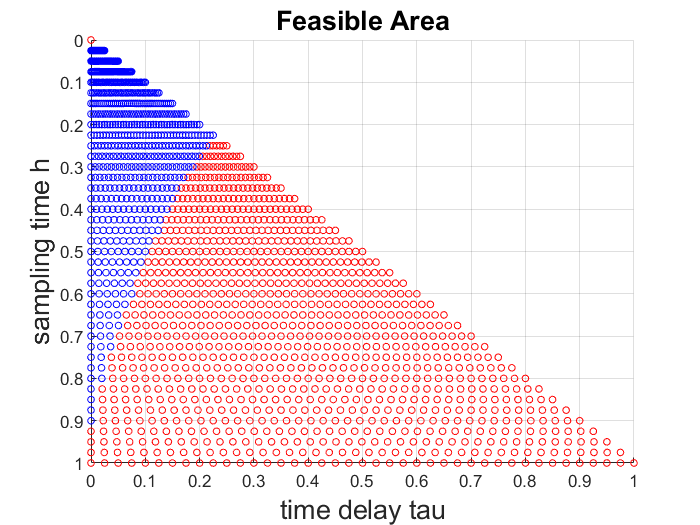


figure
inx = find(results >= 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'b', 'MarkerSize', 4)
grid on
hold on
inx = find(results < 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'r', 'MarkerSize', 4)
view(90,90)
xlabel("sampling time h", 'FontSize', 16); 
ylabel("time delay tau", 'FontSize', 16);
zlabel("\rho(F_{cl}(h, \tau))", 'FontSize', 16);
title("Feasible Area", 'FontSize', 16)